power_ratios = logspace(-1, 1, 10);

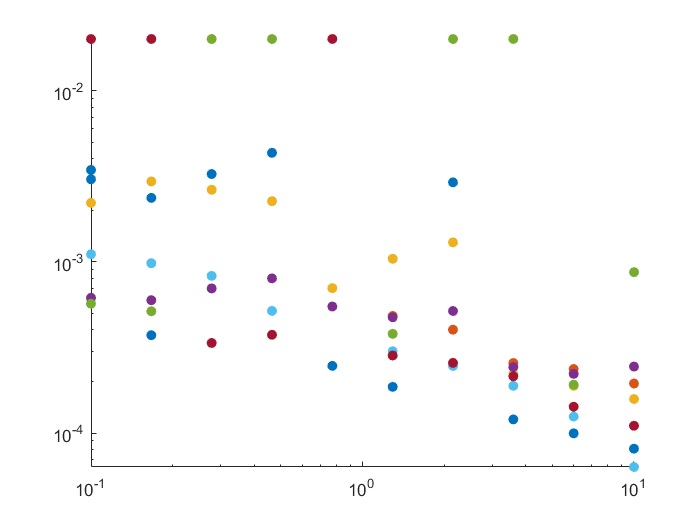

scatter(power_ratios, tau_res, 'filled')
set(gca, 'xscale','log', 'yscale','log')

tau_res_removed_anom = tau_res;
tau_res_removed_anom(:,2) = [];
tau_res_removed_anom(:,4) = [];
tau_res_removed_anom(:,5) = [];
tau_res_removed_anom(:,5) = [];
%tau_res_removed_anom(5,4) = 0.001;
tau_res_size = size(tau_res_removed_anom);

power_ratios_repd = repmat(power_ratios, tau_res_size(2), 1);
power_ratios_repd = power_ratios_repd.';

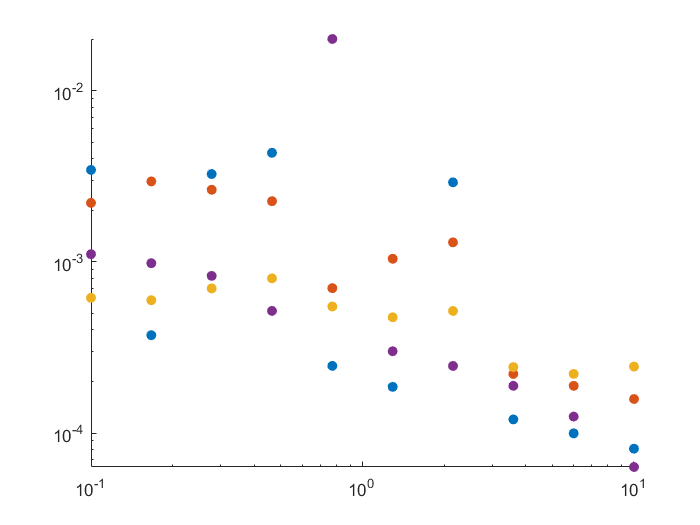

scatter(power_ratios_repd, tau_res_removed_anom, 'filled')
set(gca, 'xscale','log', 'yscale','log')
hold on

C = polyfit(log(power_ratios_repd),log(tau_res_removed_anom), 1)

C =    -0.5732   -7.4650


m = C(1);

m = -0.5732

k = C(2);

k = -7.4650

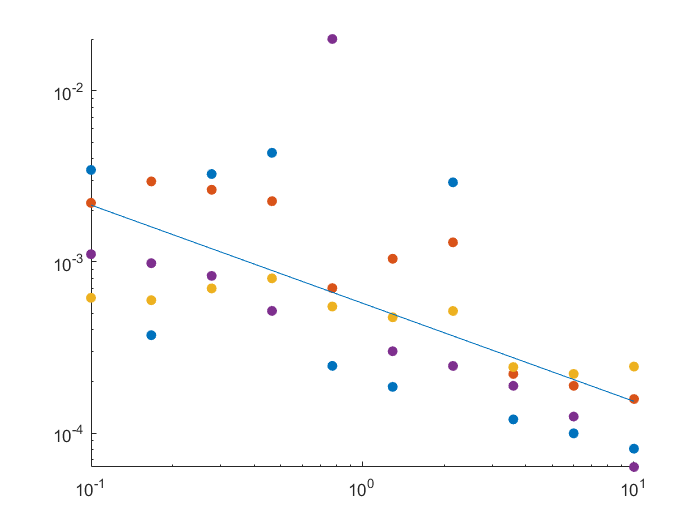

y = power_ratios_repd.^m.*exp(k);
plot(power_ratios_repd, y)

final_taus = power_ratios.^m.*exp(k)

final_taus =     0.0021    0.0016    0.0012    0.0009    0.0007    0.0005    0.0004    0.0003    0.0002    0.0002
